## Investigating gene levels in MATLAB

For the next part of this practical, we will do some basic programming to investigate trends we identified in the previous section.

Where we are using code this will be highlighted in grey. You may wish to make notes on the commands/code that we use.

Shared with you in the "Genomics Practical" folder are a seies of data files. Each of these files contains a matrix. In each matrix, every row represents a gene, and every column represents a different base pair position within that gene, as follows. Every cell contains a numeric value, corresponding to the levels of the data of interest at that particular base pair in that particular gene, as follows:

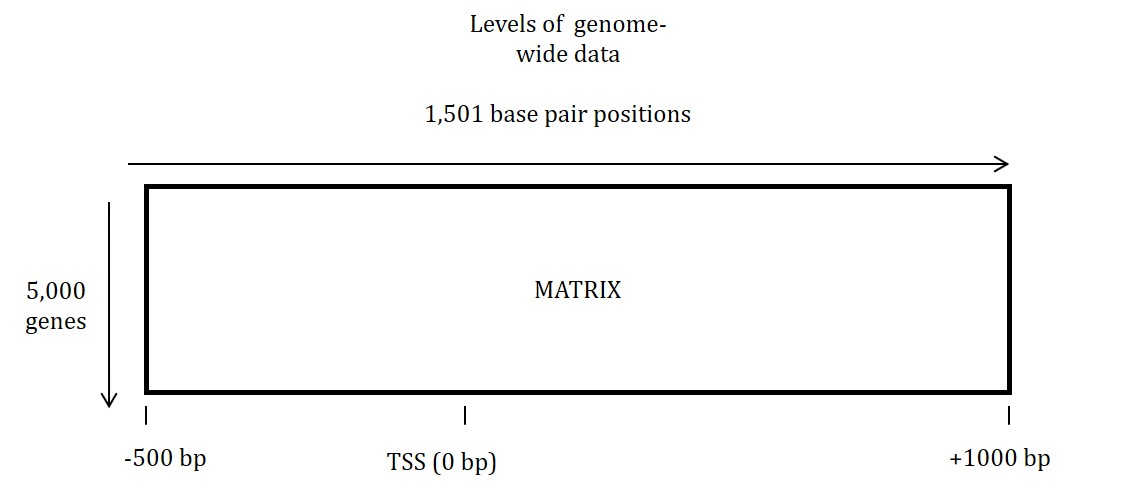

We will work through the code used to analyse this. The code will be shown in grey boxes. This is the code you could use to analyse the data the data yourself by typing these into the command window of Matlab. Clicking on the run buttons will automatically enter the code and run it so you don't need to type it.

### Heat maps

One way to look at genome-wide data is with heat maps. Here, a collection of genes are aligned by some common anchor point (typically the TSS), and stacked up one on top of the other, as in the matrix above. They’re then viewed as a heat map, where the intensity of the colour at a particular base pair for a particular gene corresponds to the level of the genomic feature at that point. This allows us to see how the levels of a feature typically vary across genes.

To achieve this in MATLAB, we can take our matrices above and use the imagesc function as shown below. First, we need to load our files into MATLAB [this loads the data into the workspace]. 

load 'Genomics Practical'/MNase_seq_glucose_gene_levels.mat
 

This data will now apear in the workspac. It is called MNase_seq_glucose_gene_levels and we can now run functions on the data. If this fails to load due to a different directory structure on your computer Click on the Home tab at the top of the screen and then Import Data. Navigate to the file and load it.

The fuction we will use is the imagesc function to visualise the data. We will then add a title using the title function and axis labels using xlabel and ylabel, colorbar to add a legend and edit the x-axis using the xticks function.

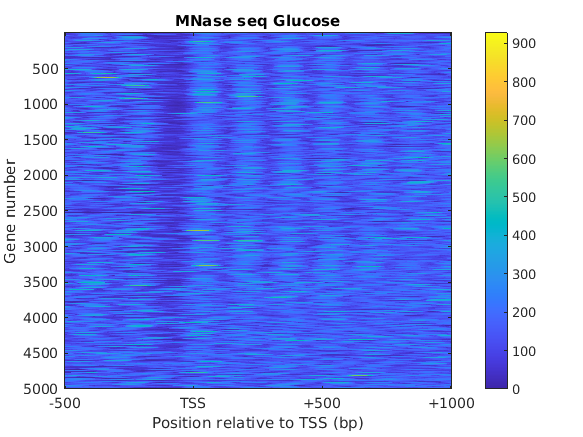

figure
imagesc(MNase_seq_glucose_gene_levels)
title('MNase seq Glucose')
xticks([1 500 1000 1500])
xticklabels({'-500','TSS','+500','+1000'})
xlabel('Position relative to TSS (bp)')
ylabel('Gene number')
colorbar

Depending on your settings this either drew an image to the right or above - to switch between click on View and selct either output on right on Inline. You should also see the data loaded into the workspace.

If you want to explore the code feel free to copy this to your command window and then edit and run.

Use the heatmap to answer questions 1-3 of the Matlab 1 quiz on Canvas.

Next, we'll load in the H3K4me3 data, and view this as a heat map too. Here we use the figure command too so that a new figure window is created and our previous figure is not replaced.

load 'Genomics Practical'/H3K4me3_ChIP_seq_glucose_gene_levels.mat
 

If this fails to load then If this fails to load due to a different directory structure on your computer Click on the Home tab and then Import Data. Navigate to the file and load it.


figure
imagesc(H3K4me3_ChIP_seq_glucose_gene_levels)
title('H3K4me3 ChIP-seq Glucose')
xticks([1 500 1000 1500])
xticklabels({'-500','TSS','+500','+1000'})
xlabel('Position relative to TSS (bp)')
ylabel('Gene number')
colorbar
 

Use this to answer questions 4 and 5 of the Matlab 1 quiz on Canvas.

Next, we can do the same for the NET-seq data:

load 'Genomics Practical'/NET_seq_glucose_gene_levels_sense_strand.mat
 

If this fails to load then If this fails to load due to a different directory structure on your computer Click on the Home tab and then Import Data. Navigate to the file and load it.


figure
imagesc(NET_seq_glucose_gene_levels_sense_strand,[-0.5,4])
title('NET-seq Glucose sense strand')
xticks([1 500 1000 1500])
xticklabels({'-500','TSS','+500','+1000'})
xlabel('Position relative to TSS (bp)')
ylabel('Gene number')
colorbar
 

Use this to answer question 6 of the Matlab 1 quiz on Canvas.

### Average gene profiles

Next, we will look at an average or ‘meta’ gene. We will produce this by averaging levels across all yeast genes, or a subgroup of genes, to get an idea of what a ‘typical’ gene looks like.

First, we will look at the average MNase-seq profile of a gene, simply by plotting the mean levels using the `mean` function. Note how we have nested this inside the plot function enabling us to calculate the mean before we plot it, without doing it seperatly

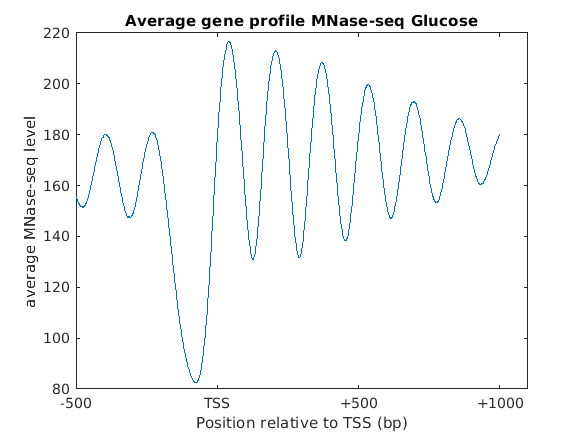

figure
plot(mean(MNase_seq_glucose_gene_levels))
title('Average gene profile MNase-seq Glucose')
xticks([1 500 1000 1500])
xticklabels({'-500','TSS','+500','+1000'})
xlabel('Position relative to TSS (bp)')
ylabel('average MNase-seq level')

Use this figure to answer questions 7 and 8 of the Matlab 1 quiz on canvas.

Next, we will compare the transcription levels in the five hundred genes with the highest and lowest levels of H3K4me3 at the +1 nucleosome. Here we are some new functions: hold on allows you to plot two things on the same plot; legend adds a figure legend to the plot.

figure
plot(mean(NET_seq_glucose_gene_levels_sense_strand(1:500,:)))
title('NET-seq data highest and lowest H3K4me3 comparison')
xticks([1 500 1000 1500])
xticklabels({'-500','TSS','+500','+1000'})
xlabel('Position relative to TSS (bp)')
ylabel('average NET-seq level')
hold on
% 'hold on' ensures that the second plot is overlain on the first, rather than replacing it.
plot(mean(NET_seq_glucose_gene_levels_sense_strand(4500:5000,:)))
legend('High H3K4me3','Low H3K4me3')
 

Using a % at the start of a line markes the line of code as a comment. This means matlab doesn't run this line - this is a useful way to mark up code to make it easier for humans to read or to remove things temporarily from your program if you are trying to troubleshoot it.

Use this figure to answer question 9 of the Matlab 1 quiz on canvas.

### Next Steps

So we have now used matlab to manipulate genomic data and produce plots on it. In the next part of the practical we will take using Matlab further to do analysis on subsets of data.

Remember at any time you can use your command window and type in code or copy and paste the 